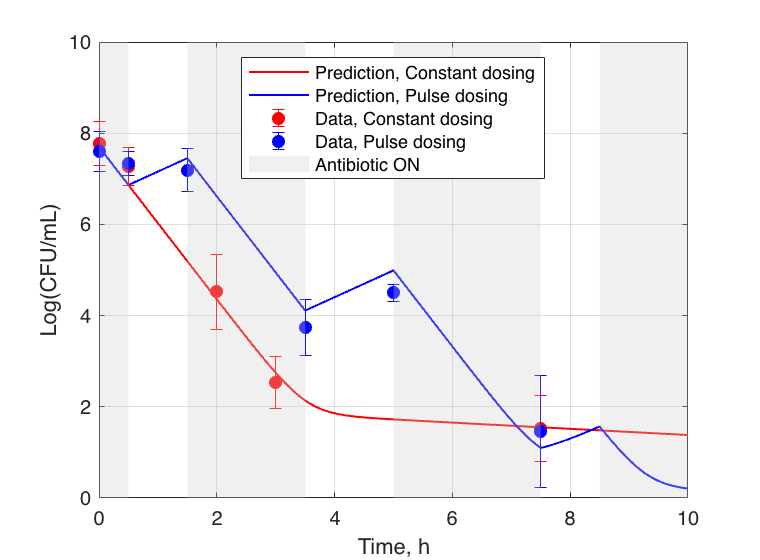

clear all
clc
close all

% import experimental data

load('Validation_Exp_03.mat');
xdata =time;
ydata =N;
error = err;



set(gcf,'position',[150,150,380,280])

N0 = 7.7;

% Parameter values estiated from Figure 6
f0 = 9.5e-7;
k1 = [-.15698 -3.8498  5e-06 0]; % [Kp_on Kn_on a_on b_on]
k2 = [-1.1598 1.354  0 1.1598]; % [Kp_off Kn_off a_off b_off]
t_total =10;

tspan = linspace(0,0.5,20);
[t,Ns] = ode45(@(t,y)odeint(t,y,k1),tspan, 10.^N0*[(1-f0),f0]);
tplot = tspan;
y_model = log10(sum(Ns,2));
            
            
tspan = linspace(0.5,1.5,30);
[t,Ns] = ode45(@(t,y)odeint(t,y,k2),tspan,[Ns(end,1), Ns(end,2)]);
tplot = [tplot,tspan];
y_model = [y_model;log10(sum(Ns,2))]; 
            
            
tspan = linspace(1.5, 3.5, 30);
[t,Ns] = ode45(@(t,y)odeint(t,y,k1),tspan,[Ns(end,1), Ns(end,2)]);
tplot = [tplot,tspan];
y_model = [y_model;log10(sum(Ns,2))];

tspan = linspace(3.5, 5, 30);
[t,Ns] = ode45(@(t,y)odeint(t,y,k2),tspan,[Ns(end,1), Ns(end,2)]);
tplot = [tplot,tspan];
y_model = [y_model;log10(sum(Ns,2))];

tspan = linspace(5, 7.5, 30);
[t,Ns] = ode45(@(t,y)odeint(t,y,k1),tspan,[Ns(end,1), Ns(end,2)]);
tplot = [tplot,tspan];
y_model = [y_model;log10(sum(Ns,2))];   

tspan = linspace(7.5, 8.5, 30);
[t,Ns] = ode45(@(t,y)odeint(t,y,k2),tspan,[Ns(end,1), Ns(end,2)]);
tplot = [tplot,tspan];
y_model = [y_model;log10(sum(Ns,2))]; 

tspan = linspace(8.5, 10, 30);
[t,Ns] = ode45(@(t,y)odeint(t,y,k1),tspan,[Ns(end,1), Ns(end,2)]);
tplot = [tplot,tspan];
y_model = [y_model;log10(sum(Ns,2))];
            
[tc,yc] = ode45(@(t,y)odeint(t,y,k1),linspace(0,t_total,80),10.^N0*[(1-f0),f0]);

plot(tc, log10(sum(yc,2)), 'r-', 'LineWidth',1)
hold on
plot(tplot', y_model, 'b-', 'LineWidth',1)
hold on

ylabel('Log(CFU/mL)');
xlabel('Time, h');
legend('P','C', Location='best')
str = sprintf('Random dosing');

xlim([0 t_total])
ylim([0 10])

grid on


errorbar(xdata(1:5,1),ydata(1:5,1),error(1:5,1), 'ro', 'MarkerFaceColor','r')
hold on
errorbar(xdata(6:end,1),ydata(6:end,1), error(6:end,1),'bo', 'MarkerFaceColor', 'b')
hold on




x1 = [0 0.5 0.5 0];
y1 = [-2 -2 10 10];
x2 = [1.5 3.5 3.5 1.5];
y2 = [-2 -2 10 10];
x3 = [5 7.5 7.5 5];
y3 = [-2 -2 10 10];
x4 = [8.5 10 10 8.5];
y4 = [-2 -2 10 10];
patch(x1,y1, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);
patch(x2,y2, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);
patch(x3, y3, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);
patch(x4, y4, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);
ticks = linspace(0,10,6);
yticks(ticks)

legend('Prediction, Constant dosing','Prediction, Pulse dosing','Data, Constant dosing', 'Data, Pulse dosing', 'Antibiotic ON', Location ='best' )

% ode integration

function [dydt] = odeint(t,y,k)
dydt=zeros(2,1);
K_p=k(1);
K_n=k(2);
a=k(3);
b=k(4);
dydt(1)= K_n*y(1)+b*y(2);
dydt(2)= a*y(1)+ K_p*y(2);
end
